clear; 

syms h u t u0 u1 um f0 f1 fm


## integration

syms alpha alpha2 v0 v1 v2
bases(t) = [1,t,t^2];
bases2(t) = [1,t,t^2,t^3]; % _2 is for 3rd degree poly integration
weights = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,1)

$$weights = \left(\begin{array}{ccc} \frac{1}{2}-\frac{1}{6\,\alpha } & -\frac{1}{6\,\alpha \,\left(\alpha -1\right)} & \frac{1}{6\,\left(\alpha -1\right)}+\frac{1}{2} \end{array}\right)$$

weights0A = int(bases / ([bases(0);bases(alpha); bases(1)]),t,0,alpha)

$$weights0A = \left(\begin{array}{ccc} -\frac{\alpha \,\left(\alpha -3\right)}{6} & \frac{\alpha \,\left(2\,\alpha -3\right)}{6\,\left(\alpha -1\right)} & \frac{\alpha^{3}}{6\,\left(\alpha -1\right)} \end{array}\right)$$

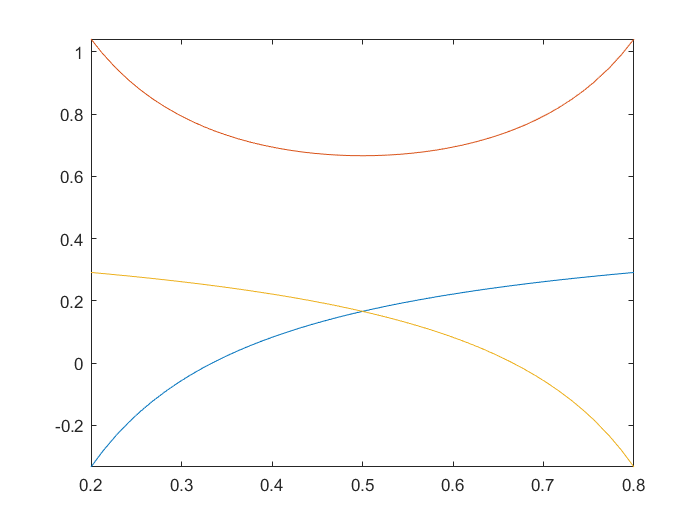

fplot(weights, [0.2,0.8])

weights2 = int(bases2 / ([bases2(0);bases2(alpha);bases2(alpha2); bases2(1)]),t,0,1)

$$weights2 = \begin{array}{l} \left(\begin{array}{cccc} \frac{\frac{\alpha }{2}-\frac{1}{6}}{\alpha }-\frac{\sigma_{1}}{\alpha \,\alpha_{2}} & \frac{2\,\alpha_{2}-1}{12\,\alpha \,\left(\alpha -\alpha_{2}\right)\,\left(\alpha -1\right)} & -\frac{2\,\alpha -1}{12\,\alpha_{2}\,\left(\alpha -\alpha_{2}\right)\,\left(\alpha_{2}-1\right)} & \frac{\frac{\alpha }{2}-\frac{1}{3}}{\alpha -1}+\frac{\sigma_{1}}{\left(\alpha -1\right)\,\left(\alpha_{2}-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha }{6}-\frac{1}{12} \end{array}$$

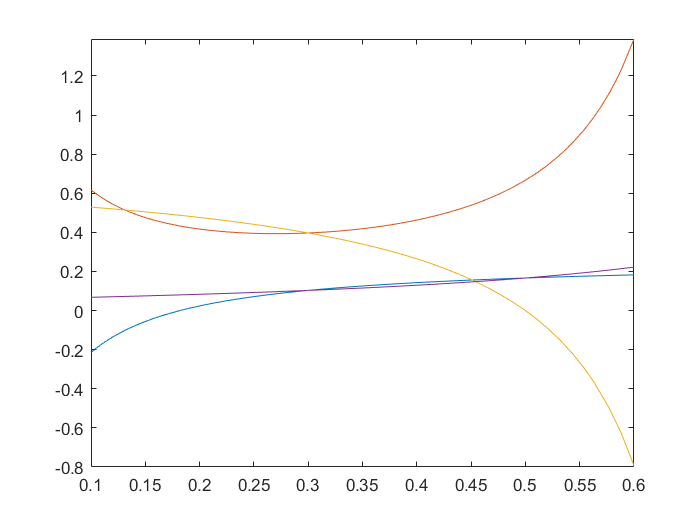

fplot(subs(weights2,alpha2,0.7), [0.1,0.6])

## input


incre01 = weights * [f0; fm; f1] * h;
incre0m = weights0A * [f0; fm; f1] * h;

## linear stability

syms lambda kappa

incre01_lam = collect(subs(expand(incre01), [f0,fm,f1], [u0*lambda,um*lambda,u1*lambda]), [u0,u1])

$$incre01\_lam = \left(\frac{h\,\lambda }{2}-\frac{h\,\lambda }{6\,\alpha }\right)\,u_{0}+\left(\frac{h\,\lambda }{2}+\frac{h\,\lambda }{6\,\left(\alpha -1\right)}\right)\,u_{1}+\frac{h\,\lambda \,\mathrm{um}}{6\,\left(\alpha -\alpha^{2}\right)}$$

incre0m_lam = collect(subs(expand(incre0m), [f0,fm,f1], [u0*lambda,um*lambda,u1*lambda]), [u0,u1])

$$incre0m\_lam = \left(\frac{\alpha \,h\,\lambda }{2}-\frac{\alpha^{2}\,h\,\lambda }{6}\right)\,u_{0}+\frac{\alpha^{3}\,h\,\lambda }{6\,\left(\alpha -1\right)}\,u_{1}+\frac{\alpha^{2}\,h\,\lambda \,\mathrm{um}}{3\,\left(\alpha -1\right)}-\frac{\alpha \,h\,\lambda \,\mathrm{um}}{2\,\left(\alpha -1\right)}$$

sol = solve([incre01_lam - (u1-u0), incre0m_lam - (um-u0)], [u1,um])

sol = 包含以下字段的 struct :
    u1: [1×1 sym]
    um: [1×1 sym]


K = subs(sol.u1/u0, [h * lambda], kappa)

$$K = -\frac{4\,\kappa -2\,\alpha \,\kappa -\alpha \,\kappa^{2}+\kappa^{2}+6}{2\,\kappa +2\,\alpha \,\kappa -\alpha \,\kappa^{2}-6}$$

## stablility region

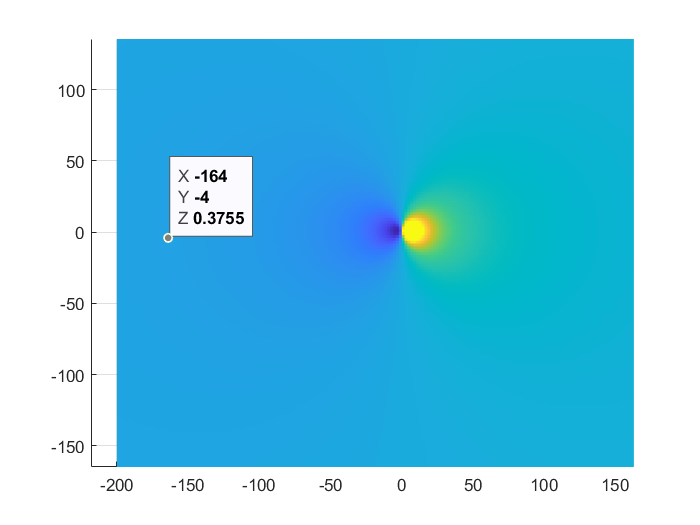

test_range = 200;
rSamp = linspace(-test_range,test_range,201);
iSamp = linspace(-test_range,test_range,201);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf = matlabFunction(symfun(K, [kappa, alpha]));
alphatest = 0.71;
% alphatest = 2/3;
KM = abs(Kf(zSampM, alphatest));

vz = min(KM,1);
% vz = double(KM > 1);
s = surf(rSampM,iSampM, ...
    vz, 'LineStyle',"none");
view(0,90)
    axis equal;

## jacobian

syms J J_m idt
c = sym("c",[4,1]);
w = sym("w",[3,1]);
JA = w(3) * J + w(2) * J_m * (J * c(4) * h + c(2))

$$JA = J\,w_{3}+J_{m}\,w_{2}\,\left(c_{2}+J\,c_{4}\,h\right)$$

JA1 = c(4)*w(2) * (J + c(2)/c(4)/h) * (J_m + w(3)/(c(4)*h * w(2))) * h

$$JA1 = c_{4}\,h\,w_{2}\,\left(J_{m}+\frac{w_{3}}{c_{4}\,h\,w_{2}}\right)\,\left(J+\frac{c_{2}}{c_{4}\,h}\right)$$

simplify(expand(JA1))

$$ans = \frac{\left(c_{2}+J\,c_{4}\,h\right)\,\left(w_{3}+J_{m}\,c_{4}\,h\,w_{2}\right)}{c_{4}\,h}$$

expand(JA - JA1)

$$ans = -\frac{c_{2}\,w_{3}}{c_{4}\,h}$$

function po = getPoly(t, h, cond)
    bases(t) = [1,t,t^2,t^3];
    dB(t) = diff(bases,t);
    valBases = [bases(0); bases(h);...
        dB(0); dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end




